% RAT SELECTION SIMULATION USING TOPSIS TECHNIQUE
% BRENDON MUTEMA (MTMBRE002)
% 22 MARCH 2024

% Number of users
N = 100;

% Create normalized weights for N users
normalised_weights = generate_weights(N);

%normalised_weights = [0.4, 0.3, 0.2, 0.1];

disp("Normalised Weights: ");

Normalised Weights: 


disp(normalised_weights)

    0.3200    0.3200    0.3600
    0.3889    0.0556    0.5556
    0.3333    0.1111    0.5556
    0.3182    0.2727    0.4091
    0.3913    0.1739    0.4348
    0.2222    0.3889    0.3889
    0.2353    0.2941    0.4706
    0.4000    0.1000    0.5000
    0.3478    0.3043    0.3478
    0.5000    0.1111    0.3889
    0.4167    0.2083    0.3750
    0.3478    0.3043    0.3478
    0.3889    0.1111    0.5000
    0.1667    0.3333    0.5000
    0.3636    0.1818    0.4545
    0.2500    0.1250    0.6250
    0.0526    0.4211    0.5263
    0.1818    0.1818    0.6364
    0.2143    0.0714    0.7143
    0.3600    0.3200    0.3200
    0.4118    0.0588    0.5294
    0.2105    0.3684    0.4211
    0.1765    0.4118    0.4118
    0.3200    0.3200    0.3600
    0.4167    0.1667    0.4167
    0.5000    0.1000    0.4000
    0.0952    0.4762    0.4286
    0.2353    0.2941    0.4706
    0.2105    0.2632    0.5263
    0.1818    0.3636    0.4545
    0.4167    0.2500    0.3333
    0.4737    0.1053    0.4211
    0.15


% % Initialize matrices to store RAT selection results
chosen_rats = strings(N, 1); % Store chosen RAT for each user

% Decision matrix
% Columns: Available Bandwidth (Mbps), Cost (per byte), Delay (ms)
% Rows: RATs (3G, 4G LTE, Wi-Fi)
decision_matrix = [
    2    0.6     20;
    60   0.5     60;
    15   0.15    100
];

disp("Decision matrix: ");

Decision matrix: 


disp(decision_matrix);

    2.0000    0.6000   20.0000
   60.0000    0.5000   60.0000
   15.0000    0.1500  100.0000




% Calculate the square root of the sum of squares for each column
column_sqrt_sum = sqrt(sum(decision_matrix.^2));

% Divide each element in the decision matrix by the corresponding square root
normalized_decision_matrix = decision_matrix ./ column_sqrt_sum;

disp("Normalised Decision Matrix: ");

Normalised Decision Matrix: 


disp(normalized_decision_matrix);

    0.0323    0.7544    0.1690
    0.9696    0.6287    0.5071
    0.2424    0.1886    0.8452



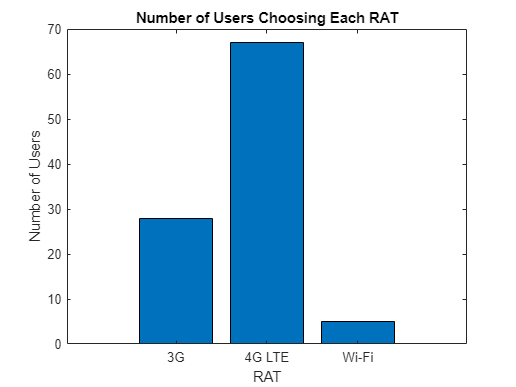


weights = normalised_weights;
% Determine the weighted normalized decision matrix for each user

for i = 1:N
    % Determine weighted normalized decision matrix
    weighted_normalized_decision_matrix = normalized_decision_matrix .* weights(i, :);
    
    % Determine the ideal and negative-ideal solutions
    ideal_solution = zeros(1, size(normalized_decision_matrix, 2));
    negative_ideal_solution = zeros(1, size(normalized_decision_matrix, 2));
    
    for col = 1:size(normalized_decision_matrix, 2)
        % For each column, determine the ideal solution based on the specified criteria
        if col == 1
            ideal_solution(col) = max(weighted_normalized_decision_matrix(:, col)); % Choose the maximum
            negative_ideal_solution(col) = min(weighted_normalized_decision_matrix(:, col)); % Choose the minimum
        elseif col == 2
            ideal_solution(col) = min(weighted_normalized_decision_matrix(:, col)); % Choose the minimum
            negative_ideal_solution(col) = max(weighted_normalized_decision_matrix(:, col)); % Choose the maximum
        elseif col == 3
            ideal_solution(col) = min(weighted_normalized_decision_matrix(:, col)); % Choose the minimum
            negative_ideal_solution(col) = max(weighted_normalized_decision_matrix(:, col)); % Choose the maximum
        end
    end
    
    % Calculate the Euclidean distances between each alternative and the ideal and negative-ideal solutions
    euclidean_distance_from_ideal = sqrt(sum((weighted_normalized_decision_matrix - ideal_solution).^2, 2));
    euclidean_distance_from_negative_ideal = sqrt(sum((weighted_normalized_decision_matrix - negative_ideal_solution).^2, 2));

    % Calculate the proximity to the ideal solution (Ci)
    proximity_to_ideal_solution = euclidean_distance_from_negative_ideal ./ (euclidean_distance_from_ideal + euclidean_distance_from_negative_ideal);

    % Find the index of the alternative with the highest Ci value
    [~, chosen_index] = max(proximity_to_ideal_solution);

    % Store chosen RAT based on Ci values
    chosen_rats(i) = sprintf('RAT-%c', char('A' + chosen_index - 1));
end

% Convert chosen_rats to a categorical array
chosen_rats = categorical(chosen_rats, {'RAT-A', 'RAT-B', 'RAT-C'});

% Count the occurrences of each RAT choice
rat_counts = countcats(chosen_rats);

% Display chosen RATs for each user
% disp('Chosen RATs for Each User:');
% disp(chosen_rats');


% Plot a bar chart to illustrate the number of users who chose each RAT
figure;
bar(rat_counts);
xlabel('RAT');
ylabel('Number of Users');
title('Number of Users Choosing Each RAT');
xticklabels({'3G', '4G LTE', 'Wi-Fi'});


% Function to assign weights


function user_weights = generate_weights(N)
    % Generates random weights (on a scale of 0 to 9) for N users across three criteria: Delay, Price, and Available Bandwidth.
    % Args:
    %   N (int): Number of users.
    % Returns:
    %   user_weights (Nx3 matrix): Each row contains three random weights (w1, w2, w3) for a user.
    % Initialize an empty matrix to store user weights
    user_weights = zeros(N, 3);
    for i = 1:N  
        % Generate random weights (on a scale of 0 to 9) for each criterion
        w1 = randi([1, 10]);  % Available Bandwidth
        w2 = randi([1, 10]);  % Cost (per byte)
        w3 = randi([7, 10]);  % Delay
        % Normalize weights to ensure they sum up to 1
        total_weight = w1 + w2 + w3;
        w1 = w1 / total_weight;
        w2 = w2 / total_weight;
        w3 = w3 / total_weight;
        % Assign the normalized weights to the matrix
        user_weights(i, :) = [w1, w2, w3];
    end
end
